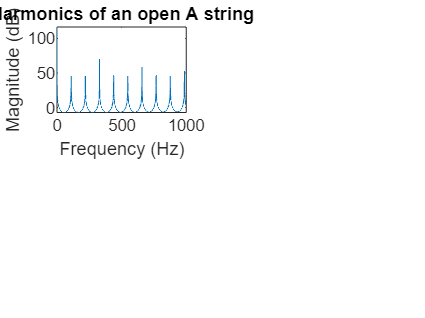

clc
clear all
Fs       = 44100;
A        = 110; % The A string of a guitar is normally tuned to 110 Hz
Eoffset  = -5;
Doffset  = 5;
Goffset  = 10;
Boffset  = 14;
E2offset = 19;
F = linspace(1/Fs, 1000, 2^12);
x = zeros(Fs*4, 1);
delay = round(Fs/A);
%generating an FIR filter with parameters b and a
b  = firls(42, [0 1/delay 2/delay 1], [0 0 1 1]);
a  = [1 zeros(1, delay) -0.5 -0.5];
[H,W] = freqz(b, a, F, Fs);
%magnitude response
subplot(2,2,1)
plot(W, 20*log10(abs(H)));
title('Harmonics of an open A string');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

zi = rand(max(length(b),length(a))-1,1);
note = filter(b, a, x, zi);
note = note-mean(note);
note = note/max(abs(note));
hplayer = audioplayer(note, Fs); play(hplayer)

Error using audioplayer
Timeout occurred while trying to communicate to the device.


%fretted string 
fret  = 4;
delay = round(Fs/(A*2^(fret/12)));
b  = firls(42, [0 1/delay 2/delay 1], [0 0 1 1]);
a  = [1 zeros(1, delay) -0.5 -0.5];
[H,W] = freqz(b, a, F, Fs);
hold on
subplot(2,2,2)
plot(W, 20*log10(abs(H)));
title('Harmonics of the A string');
zi = rand(max(length(b),length(a))-1,1);
note = filter(b, a, x, zi);
note = note-mean(note);
note = note/max(note);
hplayer = audioplayer(note, Fs); play(hplayer)
fret = [3 2 0 0 0 3];
delay = [round(Fs/(A*2^((fret(1)+Eoffset)/12))), ...
    round(Fs/(A*2^(fret(2)/12))), ...
    round(Fs/(A*2^((fret(3)+Doffset)/12))), ...
    round(Fs/(A*2^((fret(4)+Goffset)/12))), ...
    round(Fs/(A*2^((fret(5)+Boffset)/12))), ...
    round(Fs/(A*2^((fret(6)+E2offset)/12)))];


  
b = cell(length(delay),1);
a = cell(length(delay),1);
H = zeros(length(delay),4096);
note = zeros(length(x),length(delay));
for indx = 1:length(delay)
    
    % Build a cell array of numerator and denominator coefficients.
    b{indx} = firls(42, [0 1/delay(indx) 2/delay(indx) 1], [0 0 1 1]).';
    a{indx} = [1 zeros(1, delay(indx)) -0.5 -0.5].';
    
    % Populate the states with random numbers and filter the input zeros.
    zi = rand(max(length(b{indx}),length(a{indx}))-1,1);
    
    note(:, indx) = filter(b{indx}, a{indx}, x, zi);
    
    % Make sure that each note is centered on zero.
    note(:, indx) = note(:, indx)-mean(note(:, indx));
    
    [H(indx,:),W] = freqz(b{indx}, a{indx}, F, Fs);
end
subplot(2,2,[3,4])
hline = plot(W,20*log10(abs(H.')));
title('Harmonics of a G major chord');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend(hline,'G','B','D','G','B','G2');
hold on
combinedNote = sum(note,2);
combinedNote = combinedNote/max(abs(combinedNote));
hplayer = audioplayer(combinedNote, Fs); play(hplayer)
offset = 50; 
offset = ceil(offset*Fs/1000);
for indx = 1:size(note, 2)
    note(:, indx) = [zeros(offset*(indx-1),1); ...
                note((1:end-offset*(indx-1)), indx)];
end
combinedNote = sum(note,2);
combinedNote = combinedNote/max(abs(combinedNote));
hplayer = audioplayer(combinedNote, Fs); play(hplayer)


